# Prismatic Images

The `SplitChannels` function takes an RGB image `im` as argument, such as `turkeys1.jpg:` 

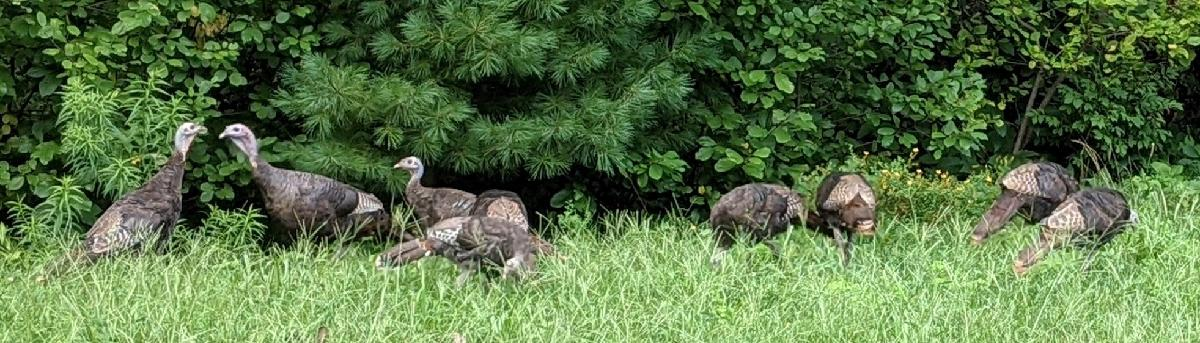

It slices off the largest possible square from the top, left-hand-side of the image; splits it into red, green, and blue channels, and then displays them on a 2x2 grid together with the comparable piece of the original image. 

function SplitChannels(im)

fullImage = imread(im);

% Determine the size of the maximal possible square
[m,n] = size(fullImage);
squareIndex = min(m,n);
squareImage = fullImage(1:squareIndex,1:squareIndex,:);

% Initialize the zero channels for the single-color images
redChannel = zeros(size(squareImage));
greenChannel = zeros(size(squareImage));
blueChannel = zeros(size(squareImage));

redChannel(:,:,1) = squareImage(:,:,1);
greenChannel(:,:,2) = squareImage(:,:,2);
blueChannel(:,:,3) = squareImage(:,:,3);

image([redChannel,greenChannel;blueChannel,squareImage])

end